clear; close all;
load('Maze.mat');

Main Loop

tic
[AStarPath, AStarCost, AStarMap, AStarStats] = run_unknown(Maze, 'A_Star');
AStarTime = toc;

tic
[DijkstraPath, DijkstraCost, DijkstraMap, DijkstraStats] = run_unknown(Maze, 'DijkstrA');
DijkstraTime = toc;

Stats and Plots

% A* path and stats
disp('--------------------------------------------');

--------------------------------------------


disp('A* Algorithm')

A* Algorithm


fprintf('  Pushes    : %d\n',   AStarStats.pushes);

  Pushes    : 17648


fprintf('  Pops      : %d\n',   AStarStats.pops);

  Pops      : 10277


fprintf('  Path cost : %.4f\n', AStarCost);

  Path cost : 118.0416


fprintf('  Time (s)  : %.6f\n', AStarTime);

  Time (s)  : 0.241595


disp('--------------------------------------------');

--------------------------------------------


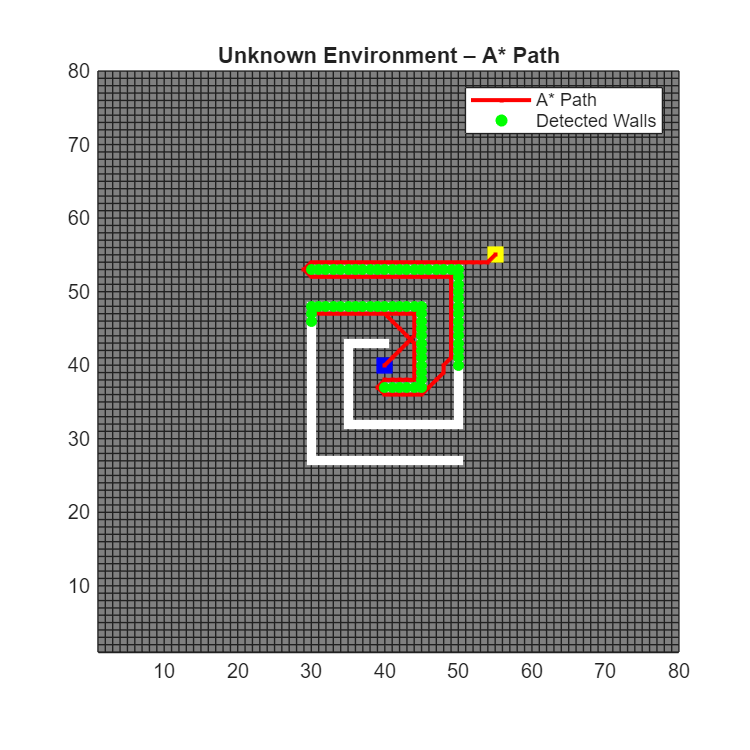

figure(1); CreateMaze_1; hold on;
p1 = plot(AStarPath(:,1), AStarPath(:,2), '.-r', 'LineWidth', 2, 'DisplayName', 'A* Path');
[sensedRows, sensedCols] = find(isinf(AStarMap));
p2 = scatter(sensedRows, sensedCols, 30, 'g', 'filled', 'DisplayName', 'Detected Walls');
legend([p1, p2], {'A* Path', 'Detected Walls'}, 'Location', 'northeast');
title('Unknown Environment – A* Path');


 
% Dijkstra path and stats
disp('--------------------------------------------');

--------------------------------------------


disp('Dijkstra Algorithm')

Dijkstra Algorithm


fprintf('  Pushes    : %d\n',   DijkstraStats.pushes);

  Pushes    : 148364


fprintf('  Pops      : %d\n',   DijkstraStats.pops);

  Pops      : 130962


fprintf('  Path cost : %.4f\n', DijkstraCost);

  Path cost : 118.0416


fprintf('  Time (s)  : %.6f\n', DijkstraTime);

  Time (s)  : 2.541125


disp('--------------------------------------------');

--------------------------------------------


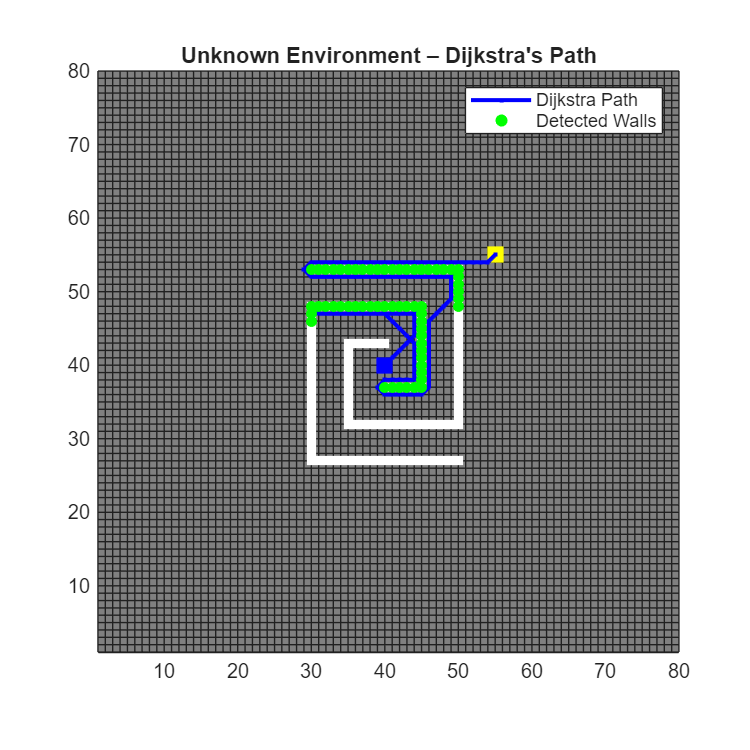

figure(2); CreateMaze_1; hold on;      
p3 = plot(DijkstraPath(:,1), DijkstraPath(:,2), '.-b', 'LineWidth', 2, 'DisplayName', 'Dijkstra Path'); 
[sensedRows, sensedCols] = find(isinf(DijkstraMap));
p4 = scatter(sensedRows, sensedCols, 30, 'g', 'filled', 'DisplayName', 'Detected Walls');
legend([p3, p4], {'Dijkstra Path', 'Detected Walls'}, 'Location', 'northeast');
title("Unknown Environment – Dijkstra's Path");